# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to November 24th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix

v=[2;5;4];
R=Eaa2rotMat(65,v);
determinant = det(R); 

**The determinant of this matrix is 1, that confirms that R is a rotation matrix.**

- Compare the transpose and the inverse of the resulting matrix

t=transpose(R);
i=inv(R);
comp=(t-i);

**When we substract the inverse of R to R transposed, the output is 0, showing that the inverse of R is equal to R transposed when we work with Rotation Matrices.**

- Using the output matrix, transform a vector parallel to the axis of rotation. 

w=v*2;
parallel_vec=R*w;

What happens?

**The transformed vector is the same as the vetor before the transform. That's because the vector is parallel to the rotation axis so it is not rotating at all.**

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the scalar product between the original vector (the unrotated vector) and the rotated one.

b=v+[0;1;0];%vector b has to be linearly independent from vector v
perpendicular_vec=cross(v,b);
perpendicular_rotated=R*perpendicular_vec;
escalar_vecs=dot(perpendicular_vec,perpendicular_rotated);
angle_result = acosd(escalar_vecs / (norm(perpendicular_vec)* norm(perpendicular_rotated)));

 What you observe? (Hint: Think about the scalar product definition)

**The angle between the 2 vectors is the same of the one in the rotation matrix, because the vectors are perpendicular to the axis of rotation and thus they get the full rotation angle.**

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

TM = zeros(1,100); %Create a column vector of the length of the amount of angles and axis that we create
for i=1:1:100 %Iterate through all the cases
    RotMat = Eaa2rotMat(theta(1,i)*(180/pi),axisM(:,i)); %Calculate the rotation matrix based on the angle and axis in the loop position
    TM(:,i) = RotMat(1,1) + RotMat(2,2) + RotMat(3,3); %Calculate the trace: sum of the elements in the main diagonal.
end

- Make a plot of the vector that you have obtained vs the theta angle. Explain why would you expect this result.

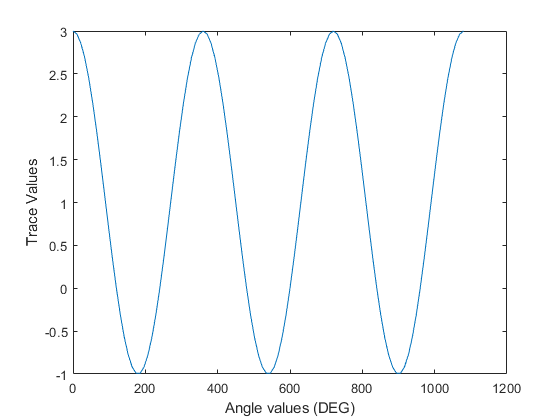

plot(theta*180/pi, TM); %Plot the results
ylabel("Trace Values");
xlabel("Angle values (DEG)");

               * Explanation here*

**The result is, as expected, a sinus function. This is expected due to that we know, based on the inverse mapping of a Rotation Matrix, that the angle only depends of the trace, and not the axis...**

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

n=[2;5;4];
n=n/sqrt(2^2+5^2+4^2);
W=Eaa2rotMat(65,n);
[a,u]=rotMat2Eaa(W);

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

**In the 3 cases, the angle is eaither 0º or 180º. Their sine is 0 and thus when we try to get the axis of rotation we get x/0, that is an indeterminate case and we cannot get the rotation vector. So we implemented a new way to solve it in our function:**

**-In the case the angle is 0º, we determined (from the rewriting of rodriges' rotation formula) that the axis is irrevelant (because we are                     not rotating at all), so we make the function bring out a generic axis.**

**-In the case the angle is 180º, we extract the first number of the axis from the re-rewriting of Rodriges' formula : [U]x^2 = R+I/2; since we know that X^2 + Y^2 + Z^2 = 1 from the inverse mapping formula of the euler principal angle. Then, we determine the other 2 numbers from this one.**

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

%We verify that our solution works
[a1,u1]=rotMat2Eaa(eye(3)); 
[a2,u2]=rotMat2Eaa([-1/3,2/3,2/3;2/3,-1/3,2/3;2/3,2/3,-1/3]);
[a3,u3]=rotMat2Eaa([0,0,-1;0,-1,0;-1,0,0]);

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ (0 , 90,0 )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ (69.282 ,69.282 ,69.282 )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ (127.279 ,-127.279 ,0 )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8

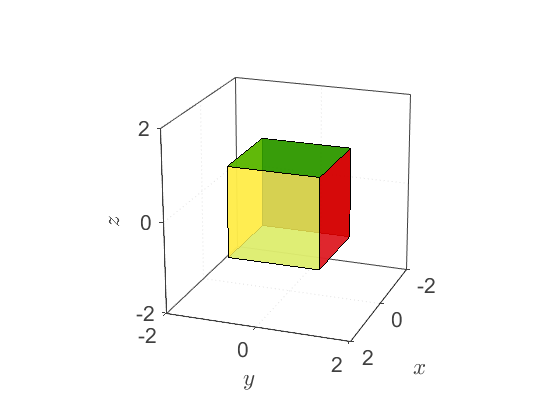

%Orientation Case 2
R1 = Eaa2rotMat(90, [0,1,0]);
RTest = Eaa2rotMat (-pi/20 * 180 / pi, [0,1,0]);
[angle1, u1] = rotMat2Eaa(R1);
r1 = angle1 * u1;

%Orientation Case 2
R2 = Eaa2rotMat(90, [0,0,1]) * Eaa2rotMat(90, [1,0,0]);
[angle2, u2] = rotMat2Eaa(R2);
r2 = angle2 * u2;

%Orientation Case 3
R3 =  Eaa2rotMat(180, [1,0,0]) * Eaa2rotMat(90, [0,0,1]);
[angle3, u3] = rotMat2Eaa(R3);
r3 = angle3 * u3;


R1 = Eaa2rotMat(angle1, u1); %Orientation Case 1
R2 = Eaa2rotMat(angle2, u2); %Orientation Case 2
R3 =  Eaa2rotMat(angle3, u3); %Orientation Case 3

M_mod = (R1*M')';  %Orientation Case 1
M_mod2 =(R2*M')'; %Orientation Case 2
M_mod3 =(R3*M')'; %Orientation Case 3


Cubeplot(M_mod);  %Orientation Case 1

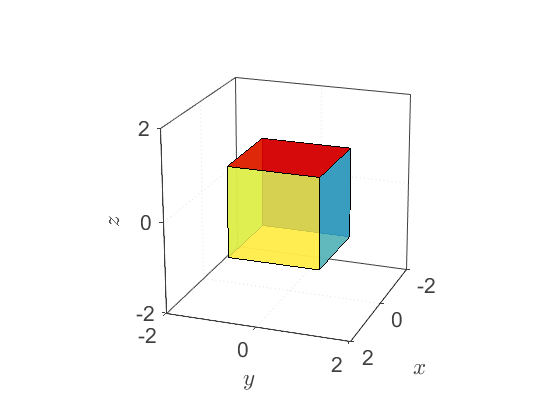

Cubeplot(M_mod2);  %Orientation Case 2

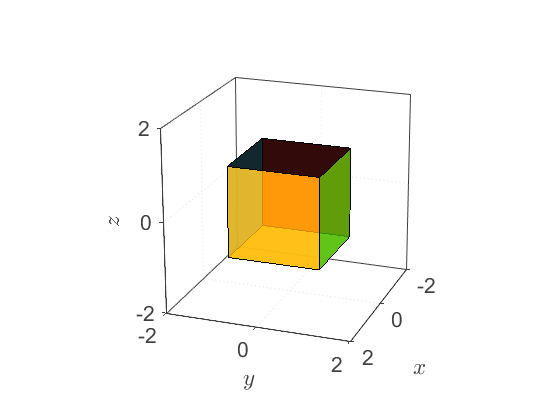

Cubeplot(M_mod3);  %Orientation Case 3

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

RotTest = eAngles2rotM(20,30,40);
detTest = det(RotTest);

- Compare the transpose and the inverse of the resulting matrix

transposedTest=transpose(RotTest);
inverseTest=inv(RotTest);
compTest=(transposedTest-inverseTest);

**When we substract the inverse of R to R transposed, the output is 0, showing that the inverse of R is equal to R transposed when we work with Rotation Matrices.**

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

k = 2;
ThetaTest = eAngles2rotM(35, (pi/2 + k*pi) * 180 / pi,65); % Make sure to input all the angles in DEG;
[yawT, pitchT, rollT] = rotM2eAngles(ThetaTest); %It works!

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.

RTTest = eAngles2rotM(75, 25,35); % Make sure to input all the angles in DEG;
[yaw, pitch, roll] = rotM2eAngles(RTTest); %Get the angles from the matrix we just calculated.